% Auto-generated by cameraCalibrator app on 10-Oct-2022
%-------------------------------------------------------


% Define images to process
imageFileNames = {'image1.jpg',...
    'image2.jpg',...
    'image4.jpg',...
    'image5.jpg',...
    'image7.jpg',...
    'image8.jpg',...
    'image9.jpg',...
    'image12.jpg',...
    'image20.jpg',...
    'image23.jpg',...
    'image25.jpg',...
    };
% Detect calibration pattern in images
detector = vision.calibration.monocular.CheckerboardDetector();
[imagePoints, imagesUsed] = detectPatternPoints(detector, imageFileNames);

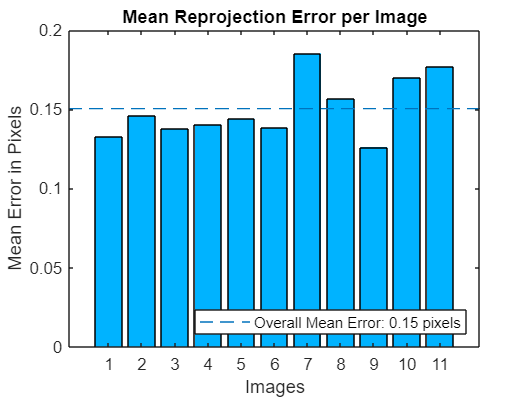

imageFileNames = imageFileNames(imagesUsed);

% Read the first image to obtain image size
originalImage = imread(imageFileNames{1});
[mrows, ncols, ~] = size(originalImage);

% Generate world coordinates for the planar pattern keypoints
squareSize = 1.950000e+01;  % in units of 'millimeters'
worldPoints = generateWorldPoints(detector, 'SquareSize', squareSize);

% Calibrate the camera
[cameraParams, imagesUsed, estimationErrors] = estimateCameraParameters(imagePoints, worldPoints, ...
    'EstimateSkew', false, 'EstimateTangentialDistortion', false, ...
    'NumRadialDistortionCoefficients', 2, 'WorldUnits', 'millimeters', ...
    'InitialIntrinsicMatrix', [], 'InitialRadialDistortion', [], ...
    'ImageSize', [mrows, ncols]);

% View reprojection errors
h1=figure; showReprojectionErrors(cameraParams);

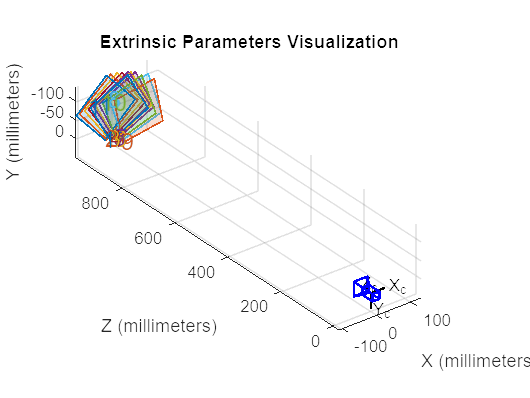


% Visualize pattern locations
h2=figure; showExtrinsics(cameraParams, 'CameraCentric');


% Display parameter estimation errors
displayErrors(estimationErrors, cameraParams);


			Standard Errors of Estimated Camera Parameters
			----------------------------------------------

Intrinsics
----------
Focal length (pixels):   [ 1474.4768 +/- 150.0318   1476.0782 +/- 150.4727]
Principal point (pixels):[  583.1370 +/- 8.6392      432.1850 +/- 8.3792  ]
Radial distortion:       [    0.3176 +/- 0.0841       -7.9801 +/- 4.1475  ]

Extrinsics
----------
Rotation vectors:
                         [   -0.0768 +/- 0.0065       -0.0327 +/- 0.0064       -2.2954 +/- 0.0003  ]
                         [   -0.0697 +/- 0.0061       -0.0445 +/- 0.0068       -2.2484 +/- 0.0004  ]
                         [   -0.0669 +/- 0.0059       -0.0451 +/- 0.0067       -2.1838 +/- 0.0004  ]
                         [   -0.0592 +/- 0.0057       -0.0453 +/- 0.0068       -2.1370 +/- 0.0003  ]
                         [   -0.0599 +/- 0.0057       -0.0446 +/- 0.0065       -2.0703 +/- 0.0004  ]
                         [   -0.0594 +/- 0.0056       -0.0528 +/- 0.0064       -2.0451 +/- 0.0004  ]
 


% For example, you can use the calibration data to remove effects of lens distortion.
undistortedImage = undistortImage(originalImage, cameraParams);

% See additional examples of how to use the calibration data.  At the prompt type:
% showdemo('MeasuringPlanarObjectsExample')
% showdemo('StructureFromMotionExample')
